clearvars
clear
clc
%stock the audioData
wavFile = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav'

wavFile = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav'

[signal,Fs] = audioread(wavFile);
signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =     0.0003
    0.0008
    0.0014
    0.0019
    0.0025
    0.0032
    0.0042
    0.0052
    0.0066
    0.0080


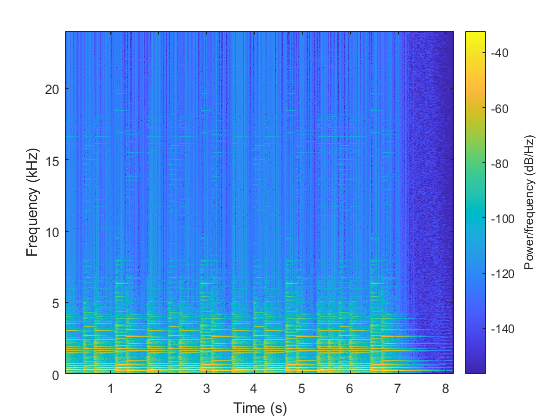

%parametre

FFTSize = 4096;
hopsize = 200; %changer de nom overlapp, overlap = nombre de samples commun
overlapp = FFTSize -hopsize;

filterOrder = 3;
cutoff = 37;
cutoffRad = cutoff/Fs/2;

downSamplingFactor = 16;


spectrogram (signal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')

N = length(signal)

N = 394222

time = [0:N-1]/Fs

time =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010



%le nombre de FFT a effectuer pour couvrir tout le signal
numberFFT  = floor((N-FFTSize)/hopsize);

audio = miraudio(wavFile,'Normal');

Computing miraudio related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Elapsed time is 0.219220 seconds.


mirfilter = mirfilterbank(audio);

Computing mirfilterbank related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...


filterdata = mirgetdata(mirfilter);
filteredSignal = filterdata(:,:,7)

filteredSignal =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0001


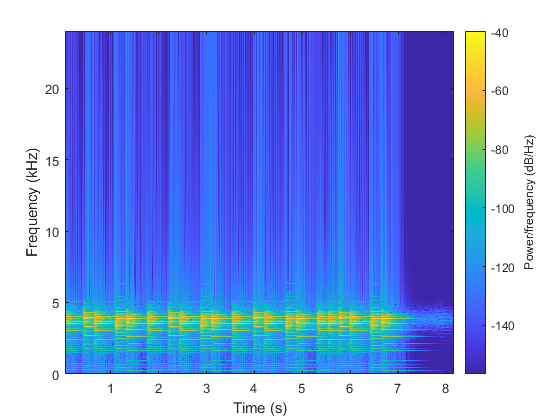

spectrogram (filteredSignal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')
hold off;


[b,a] = butter(filterOrder,cutoffRad);
sys = tf(b,a,1/Fs)

sys =
 
  2.216e-10 z^3 + 6.649e-10 z^2 + 6.649e-10 z + 2.216e-10
  -------------------------------------------------------
            z^3 - 2.998 z^2 + 2.995 z - 0.9976
 
Sample time: 2.0833e-05 seconds
Discrete-time transfer function.



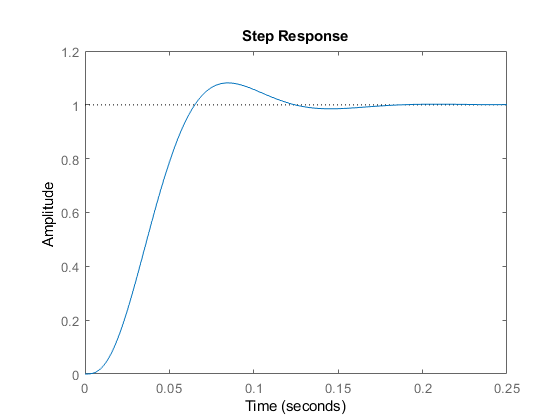

step(sys)

iir = dsp.IIRFilter('Numerator',b,'Denominator',a);
enveloppe = iir(abs(filteredSignal))

enveloppe =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


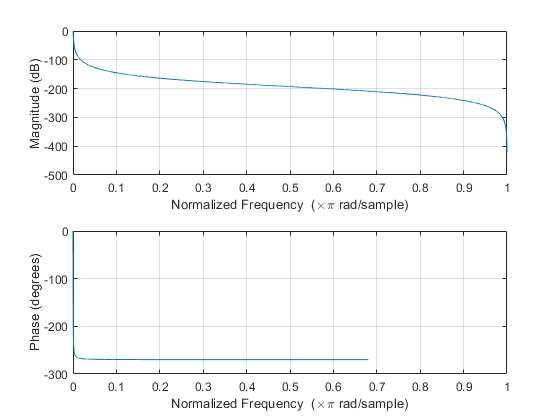



freqz(b,a,10000)

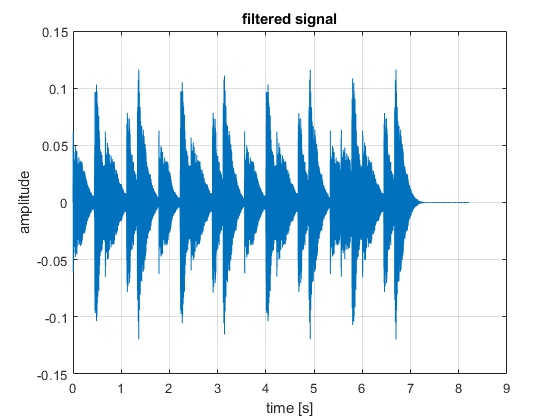


enveloppe = enveloppe(1:downSamplingFactor:end);
timedown = time(1:downSamplingFactor:end);

diffOutput = enveloppe(2:end) - enveloppe (1:end-1);
diffOutput = max(diffOutput,0);
maxOfDiff = max(diffOutput);
diffOutput = diffOutput/maxOfDiff;

plot(time,filteredSignal)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("filtered signal")

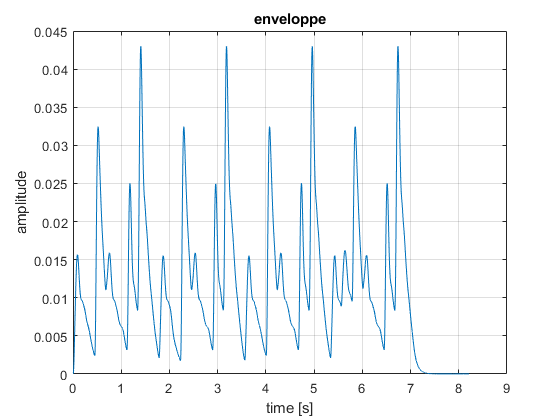


plot(timedown,enveloppe)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("enveloppe")

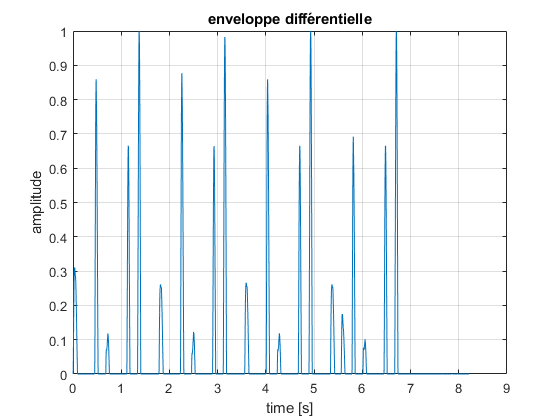


plot(timedown(1:end-1),diffOutput)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("enveloppe différentielle")